# Algoritmos Numéricos por Computadora

# Examen Final - Otoño 2019

**Cambia el nombre del script a NombreClaveúnica (ej: Marcelo123456).**

**Sube tu archivo resultado a comunidad **$\to$** Examen Final antes de las 2pm.**

**Al correr tu script deben desplegarse los resultados.**

**1a.** Escribe, al final del script, la función * jacobiana(f,x)* que calcula numéricamente la matriz jacobiana de la función vectorial $f$ en el vector $x$.

**1b. **Escribe, al final del script, el método de *Newton-Raphson *de varias variables modificado para que no reciba la matriz jacobiana sino que la calcule en cada iteración utilizando la función del problema 1. *NewtonRaphsonVVn(f,x)*

**2. **Utiliza el (nuevo) método de Newton-Raphson de varias variables para determinar puntos de intersección entre la circunferencia $x^2 +y^2 =3$ y la hipérbola $\mathit{xy}=1$.

%solución utilizando newton raphson anterior
f = @(x) [x(1).^2 + x(2).^2-3;x(1).*x(2)-1];

J = @(x) [2*x(1)  2.*x(2); x(2) x(1)];

c= @(x,y) x.^2 + y.^2 -3;
zhandle = fcontour(c);
grid on;
hold on;
h= @(x,y) x*y-1;
xhandle = fcontour(h);

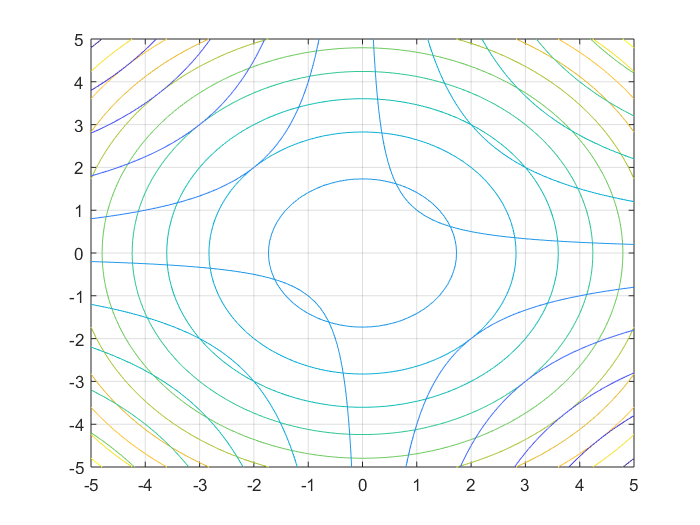

hold off;


%viendo la gráfica vemos que la intersección es entre -2 y 0 & 1 y 3
x0 = [-2; 0];
disp(" raices entre -2 y 0");

 raices entre -2 y 0


[x,i] = NewthonRaphsonVV(f,J,x0)

x =    -1.6180
   -0.6180


i = 7

x0 = [1; 3];
disp(" raices entre -2 y 0");

 raices entre -2 y 0


[x,i] = NewthonRaphsonVV(f,J,x0)

x =     0.6180
    1.6180


i = 7

**3.** Usando uno de los métodos vistos en clase para encontrar raíces de ecuaciones, calcula  una aproximación a $\sqrt[3]{25}\ldotp$

% Solución
resp = 25^(1/3)

resp = 2.9240

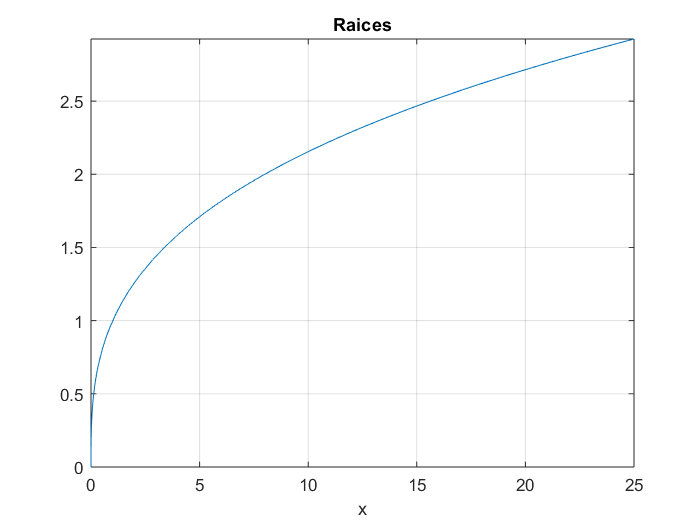


f = @(x) x.^(1/3);
a = 0;
b = 25;
fplot(f,[a,b]);
xlabel('x');
title('Raices');
grid on;

[x,i,~] = newtownRaphsonOptimizacion(f,2.5,3)

x = 3.3896e+21

i = 53

**4.** Para simular el crecimiento de una población se utiliza el modelo logístico:


$$\frac{\textrm{d}}{\textrm{d}t}p=k_{\mathrm{gm}} \left(1-\frac{p}{p_{\mathrm{max}} }\right)p$$


donde $p$ es la población, $k_{\mathrm{gm}}$ es la tasa máxima de crecimiento en condiciones ilimitadas y $p_{\mathrm{max}}$ es la capacidad de carga. Simula la población mundial entre 1950 y 2020. Para la simulación utiliza las siguientes condiciones iniciales y valores de parametros: 

$p_0$ (en 1950) = 2,555 millones de personas, $k_{\mathrm{gm}} =0\ldotp 026$/año y $p_{\mathrm{max}}$= 12,000 millones de personas.

En la simulación, usa los métodos de Euler y RK4 (con la misma h) para encontrar ¿cuántos millones de personas habrá en 2020? 

¿Por qué los resultados son diferentes al usar los dos métodos? ¿Cuál crees que es más exacto? ¿Por qué?

% Solución
p0= 2555;
kgm= 0.026;
pmax = 12000;
f = @(t,y) kgm*(1-(y/pmax))*y;
h=5;
t0=1950;
tf=2020;
[t,y] = ivps(f,t0,p0,h,tf,'rk4');
plot(t,y)
xlabel('t');
ylabel('y');
grid on;
hold on;
millonesRk4 = y(end)

millonesRk4 = 7.5049e+03

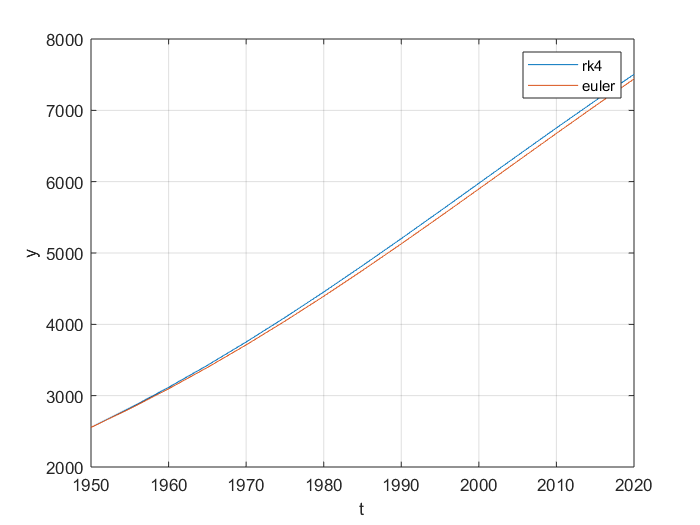


[tiemp,p] = ivps(f,t0,p0,h,tf,'euler');
plot(tiemp,p)
xlabel('t');
ylabel('y');
grid on;
legend('rk4','euler')
hold off;

millonesEuler = p(end)

millonesEuler = 7.4400e+03

**Respuesta pregunta 4: **

En 2020 utilizando el método de RK4 habrán más personas que utilizando el método de Euler. El método de Euler es un poco más confiable en este caso ya que la ecuación diferencial a resolver es lineal y el método de euler es exacto siempre y cuando la solución sea lineal, RK4 es mejor utilizarlo cuando se tiene un polinomio de grado 4 o menor

**5.** Si se drena el agua desde un tanque cilíndrico vertical abriendo una válvula en la base, el liquido fluirá rápido cuando el tanque esté lleno y despacio cuando se drene. Como resultado, la tasa a la que el nivel del agua disminuye es:

$\frac{\textrm{d}}{\textrm{d}t}y=-k\sqrt{y}$               ($y$ es el nivel del agua en metros y $t$ es el tiempo en minutos)

donde $k$ es una constante que depende de la forma del agujero y del área de la sección transversal del tanque y del agujero. 

¿En cuántos minutos se vacía un tanque si el nivel inicial del agua en el tanque es de 3m y $k=0\ldotp 06$?


syms y(t) k
eqny = diff(y,t,1)== -k*sqrt(y)

$$eqny(t) = \frac{\partial }{\partial t}y\left(t\right)=-k\,\sqrt{y\left(t\right)}$$

yG = dsolve(eqny)

$$yG = \left(\begin{array}{c} 0\\ \frac{{\left(C_{10}-k\,t\right)}^{2}}{4} \end{array}\right)$$

cond1 = y(0) == y0

$$cond1 = y\left(0\right)=3$$

yP = dsolve(eqny,cond1)

$$yP = \left(\begin{array}{c} \frac{{\left(k\,t+\sqrt{12}\right)}^{2}}{4}\\ \frac{{\left(k\,t-\sqrt{12}\right)}^{2}}{4} \end{array}\right)$$


k=0.06;
y0=3;
xS = subs(yP) % subs es symbolic substitution

$$xS = \left(\begin{array}{c} \frac{{\left(\frac{3\,t}{50}+\sqrt{12}\right)}^{2}}{4}\\ \frac{{\left(\frac{3\,t}{50}-\sqrt{12}\right)}^{2}}{4} \end{array}\right)$$

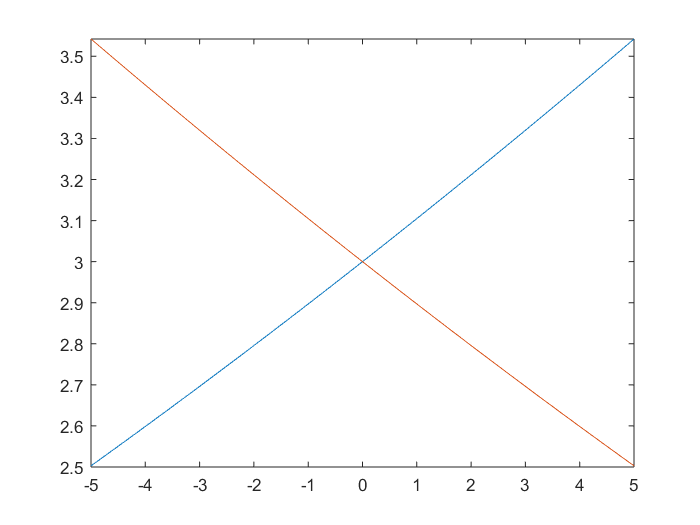

fplot(xS(1),[-5,5]);
hold on;
fplot(xS(2),[-5,5]);
hold off;

[t,i] = newtonRaphson(xS,-7,7)

Array indices must be positive integers or logical values.

Error in sym/subsref (line 890)
            R_tilde = builtin('subsref',L_tilde,Idx);

Error in newtonRaphson (line 18)
        x = xp - f(xp) /df(xp);

**6. ** Explica por qué el siguiente programa imprime 'Suma incorrecta'

num2hex(0.1)
suma = 0;
for i=1:10
    suma = suma + 0.1;
end
if (suma == 1)
    disp('Suma correcta')
else
    disp('Suma incorrecta')
end

**La suma es incorrecta por los errores de precisión al utilizar decimales en matlab, puede ser que haya algún decimal que haga que el resultado de suma no sea tomado como 1. **

**7.** A partir de la matriz X=rand(5), determina de la manera más compacta posible cuántos elementos son mayores a 0.5. Después, resta 0.5 a todos los valores que son mayores a  0.5 e imprime la matriz resultante. Cuenta cuántos elementos de esta matriz son mayores que 0.5 (la respuesta debe ser 0).

X = rand(5)

X =     0.7577    0.7060    0.8235    0.4387    0.4898
    0.7431    0.0318    0.6948    0.3816    0.4456
    0.3922    0.2769    0.3171    0.7655    0.6463
    0.6555    0.0462    0.9502    0.7952    0.7094
    0.1712    0.0971    0.0344    0.1869    0.7547


cantidad = numel(X(X>0.5)) % cantidad elementos mayores a 0.5

cantidad = 12

X(X>0.5) = X(X>0.5) -0.5   % restarle 0.5 a los elementos mayores a 0.5

X =     0.2577    0.2060    0.3235    0.4387    0.4898
    0.2431    0.0318    0.1948    0.3816    0.4456
    0.3922    0.2769    0.3171    0.2655    0.1463
    0.1555    0.0462    0.4502    0.2952    0.2094
    0.1712    0.0971    0.0344    0.1869    0.2547


mayores = numel(X(X>0.5))  % cantidad elementos mayores a 0.5 despues de la resta

mayores = 0

## Escribe aquí la respuesta a la pregunta 1a

function J = jacobiana( f,x )      

end

## Escribe aquí la respuesta a la pregunta 1b

function [ x,i ] = NewtonRaphsonVVn( f, x )

end

## Escribe aquí otras funciones que utilices

% Otras funciones
function [x,i] = NewthonRaphsonVV(f,J,x)
    tol = eps();
    MAX=53;
    fa = f(x);
    i=0;
    condition = any(fa);
    
    while condition
        xp = x;
        fa= f(xp);
        x = xp-J(xp)\fa;
        i=i+1;
       condition = i< MAX &&any(f(x))&& norm((x-xp)./x,Inf)>tol ;
    end
end

function [t,y] = ivps(f,t0,y0,h,tf,metodo)
 %solucionador de problemas con valor inicial
 % y' = f(t,y)   y(0)=y0
 
    switch metodo
        case 'euler'
            solver = @euler; 
            
        case 'midpoint'
            solver = @midpoint;
            
        case 'trapezoide'
            solver = @trapezoide; 
            
        case 'rk4'
            solver = @rk4; 
            
        otherwise
            error('Método desconocido');
    end
    
    t = t0:h:tf;
    y = zeros(length(y0),length(t));
    y(:,1) = y0;
    for i=1:1:length(t)-1
        y(:,i+1) = y(:,i) + solver(f,t(i),y(:,i),h)*h; 
    end

end

function phi= euler(f,t,y,~)
    phi = f(t,y);
end

function phi= midpoint(f,t,y,h)
    s1=f(t,y);
    ym= y + s1*(h/2);
    phi=f(t+h/2,ym);
end

function phi= trapezoide(f,t,y,h)
        s1=f(t,y);
        yf=y+h*s1;
        s2=f(t+h,yf);
        phi =(s1+s2)/2;     
end

function phi = rk4(f,t,y,h)
        s1 = f(t,y);
        s2 = f(t+h/2, y + (h/2)*s1);
        s3 = f(t+h/2, y + (h/2)*s2);
        s4 = f(t+h, y + h*s3);
        phi = (s1 + 2*s2 + 2*s3 + s4)/6;
end

function [x,i,min] = newtownRaphsonOptimizacion(f,a,b)

fsym = sym(f); % convierte la función f a simbolica para poder derivar
    dfs = diff(fsym); % deriva simbolicamente
    df= matlabFunction(dfs);
    dfs2 = diff(dfs);
    df2 = matlabFunction(dfs2);
    
 x= (b+a)/2;
    
    tol = eps();
    MAX=53;
    i=0;
    
    condition = true;
    
    %será un do while
    while condition
        xp = x;
        x = xp - df(xp) /df2(xp);
        i=i+1;
        condition = abs((x-xp)/x)> tol && df(x)~=0 && i<MAX;
       
    end
    % if df2(x) > 0
     %       min = true;
     %   else
      %      min =false;
       % end
    min = df2(x)>0; 
    
end